## MSE 491 DSP - Lab Assignment 2

Authors:

- Abdullah Amjad - 301414558

- Tony Nguyen - 301286979

Created: 15 June 2022

Modified: 21 June 2022

clear all
close all
clc

## Loading Variables

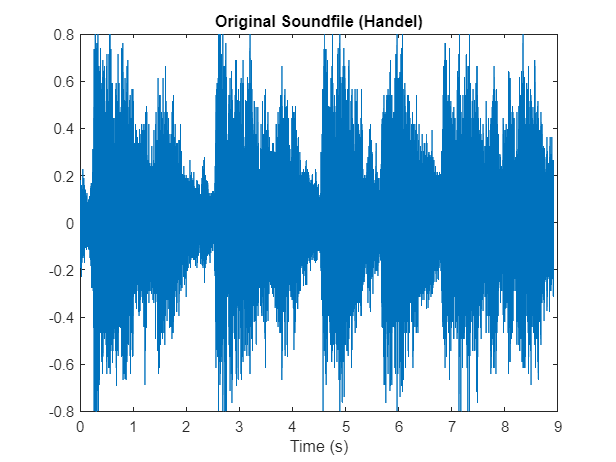

% Loading audio
% Import carrier signal
load handel
Ts = 1/Fs;
N = length(y);
t = [0:N-1]*Ts; t = t(:);

figure
plot(t,y);title('Original Soundfile (Handel)');
xlabel('Time (s)');

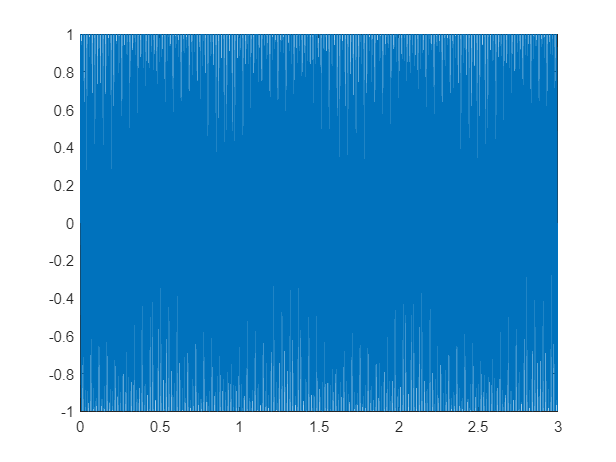

% Alternate audio loading - Sine wave that is easier to visualize audio effects
Fs = 48000;
Ts = (1/Fs);
t = 0:Ts:3;
t = t(:);
f = 100; phi = 0;
y = sin(2*pi*f.*t + phi);
figure(1);
plot(t,y);

## Fade-in/out

% Fade-in/out: the user can set a fade-in/out in volume effect. The type of fade is 
% user-selectable between linear fade, or exponential fade. The start and stop time 
% of the fade effect is user-selectable with reasonable default values. 
% Variable Setup
fadeTime = 1.5; %user definable, should have different times for fade in and out?
numOfSamples = fadeTime*Fs; %fade in/out

### Linear Fade

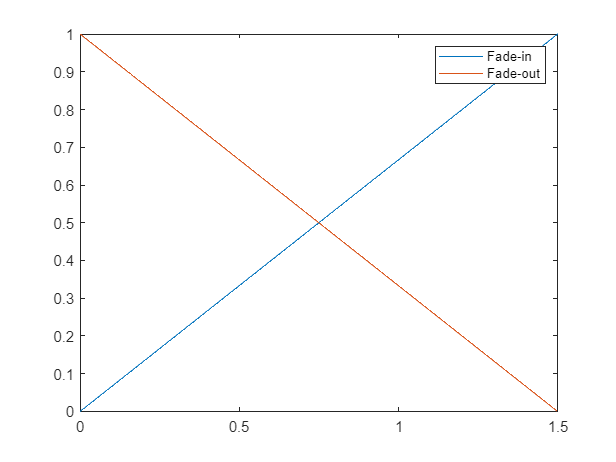

a = linspace(0,1,numOfSamples); a = a(:); %1 in linspace is the volume of fade in/out, do not change
LinFadeIn = a;
LinFadeOut = 1-a; % Equivalent = linspace(1,0,numOfSamples);

%For testing
figure(2); 
plot(fadeTime*a,LinFadeIn,fadeTime*a,LinFadeOut);legend('Fade-in','Fade-out');

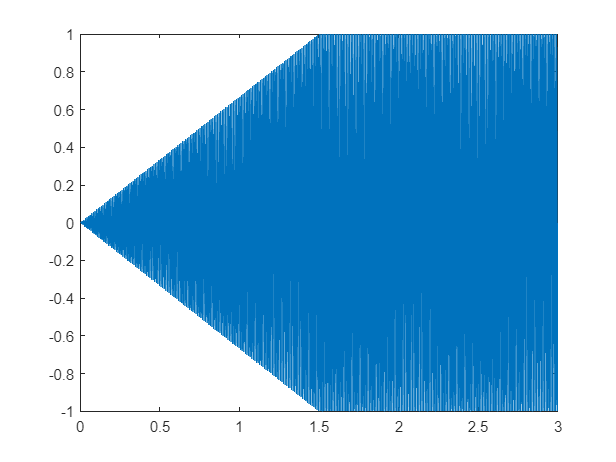

% Linear Fade–in
% Index samples just at the start of the signal
temp = y;
temp(1:numOfSamples) = LinFadeIn .* y(1:numOfSamples);

%For testing
soundsc(temp, Fs);
figure(3);
plot(t,temp)

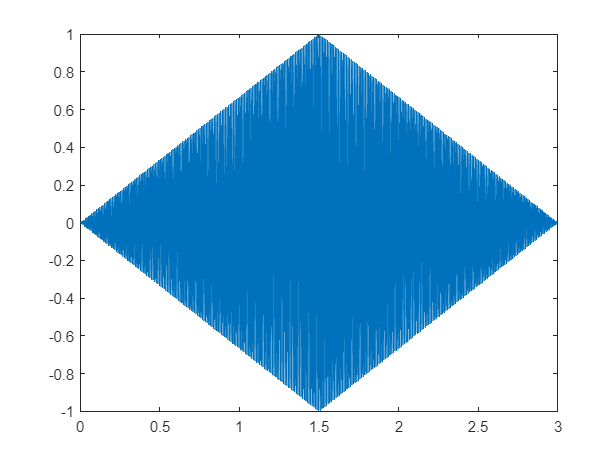

% Linear Fade–out
% Index samples just at the end of the signal
out = temp;
out(end-numOfSamples+1:end) = LinFadeOut.*temp(end-numOfSamples+1:end);

%For testing
soundsc(out, Fs);
figure(4);
plot(t,out);

### Exponential Fade

% Variable setup
numOfSamples = fadeTime*Fs;
x = 2; % Exponent for curve; user defianble? has to be > 1

#### Convex Fades

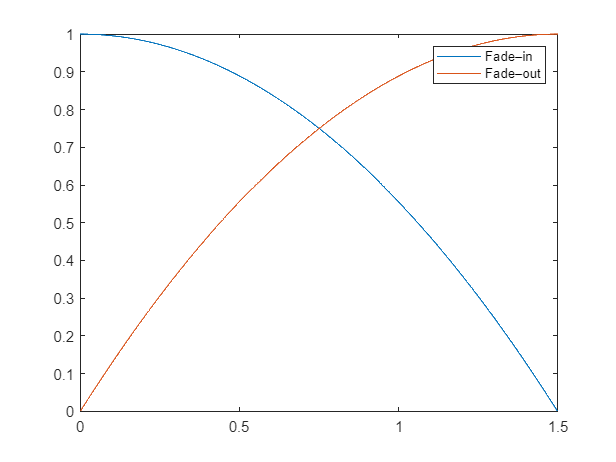

a = linspace(0,1,numOfSamples); a = a(:);
VexExpFadeOut = 1 - a.^x;

a = linspace(1,0,numOfSamples); a = a(:);
VexExpFadeIn = 1 - a.^x;

% For Testing
figure(2);
plot(fadeTime*a,VexExpFadeIn,fadeTime*a,VexExpFadeOut);legend('Fade–in','Fade–out');

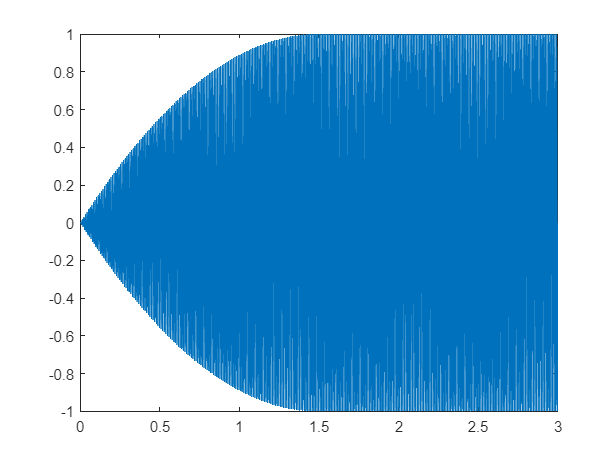

% Convex Fade–in
temp = y;
temp(1:numOfSamples) = VexExpFadeIn .* y(1:numOfSamples);

soundsc(temp, Fs);
figure(3);
plot(t,temp);

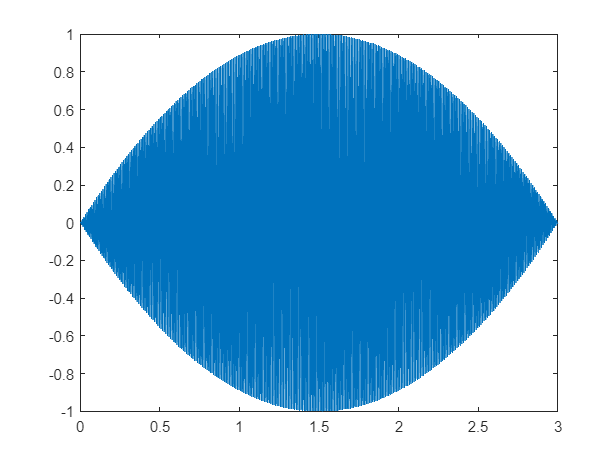

% Convex Fade–out
out = temp;
out(end-numOfSamples+1:end) = VexExpFadeOut.*temp(end-numOfSamples+1:end);

soundsc(out, Fs);
figure(4);
plot(t,out);

#### Concave Fades

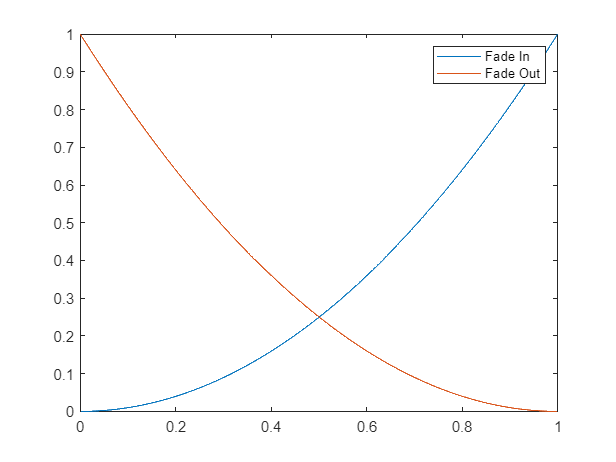

a = linspace(0,1,numOfSamples); a = a(:);
CavExpFadeOut = a.^x;

a = linspace(1,0,numOfSamples); a = a(:);
CavExpFadeIn = a.^x;

figure(5);
plot(fadeTime*a,CavExpFadeIn,fadeTime*a,CavExpFadeOut);legend('Fade In','Fade Out');

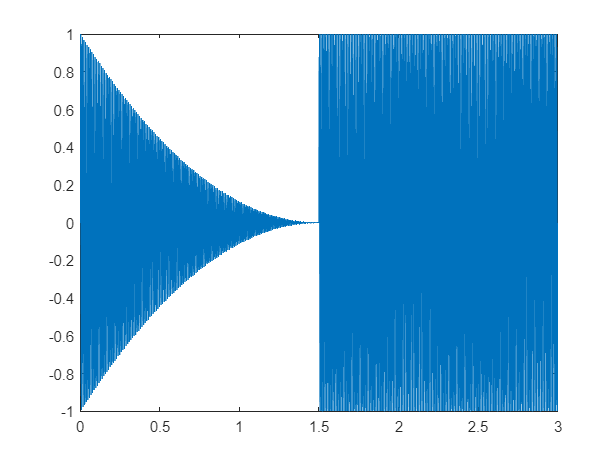

% Concave Fade–in
temp = y;
temp(1:numOfSamples) = CavExpFadeIn .* y(1:numOfSamples);

soundsc(temp, Fs);
figure(3);
plot(t,temp);

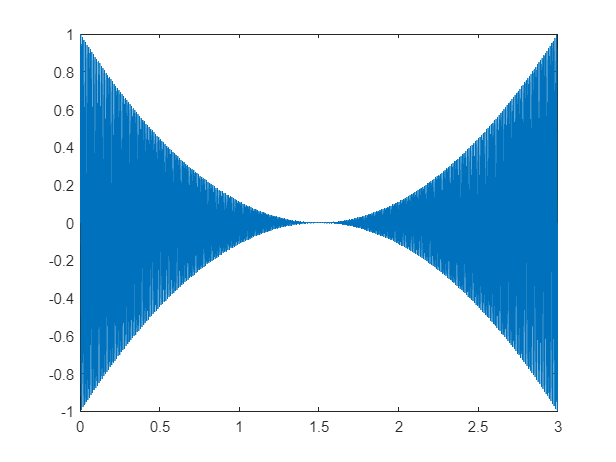

% Convex Fade–out
out = temp;
out(end-numOfSamples+1:end) = CavExpFadeOut.*temp(end-numOfSamples+1:end);

soundsc(out, Fs);
figure(4);
plot(t,out);

## Tremelo

% Tremolo parameters;
depth = 100; %user definable; intensity of effect: chamged amplitude and offset; ranges from [0,100]%
speed = 3; %user definable; frequency of effect; ranges from [0.1,20] Hz
waveType = 0; %user definable; select between sine, square, triange, sawtooth

amp = 0.5*(depth/100);
offset = 1 - amp;

% Synthesize of modulation signal
f = speed; % speed of effect
phi = 0; %set by user? is this needed?

% wil these be used in any other effects?
sine = sin(2*pi*f.*t+phi); %sin wave
sqre = square(2*pi*f.*t+phi); %square wave
tri = sawtooth(2*pi*f.*t+phi, 0.5); %triangle wave; set 'xmax' to 0.5 in sawtooth function
saw = sawtooth(2*pi*f.*t+phi); %sawtooth wave

waveType = 2; %for testing
%% will integrate with Abdullah's code
switch waveType
    case 0
        sw = sine;
    case 1
        sw = sqre;
    case 2
        sw = tri;
    case 3
        sw = saw;
end 

mod = amp.*sw + offset;

% Plot to compare the original wave with the modulator
% Index only first second of signal for visualization purposes
figure
plot(t(1:Fs),sw(1:Fs),t(1:Fs),mod(1:Fs));
legend('OG','Modulated');
title('Modulator Signal');

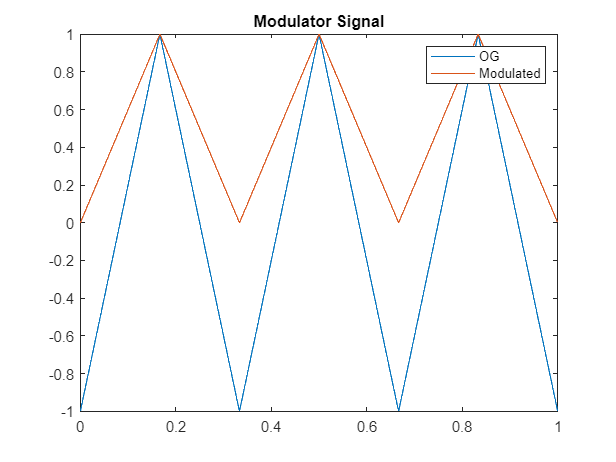

% Modulate the amplitude of the carrier by the modulator
output = y.*mod;


% Plot the output and listen to the result

sound(output,Fs);
figure
plot(t,output);
title('Output Signal (Processed)');

## Rythmic Auto Panning

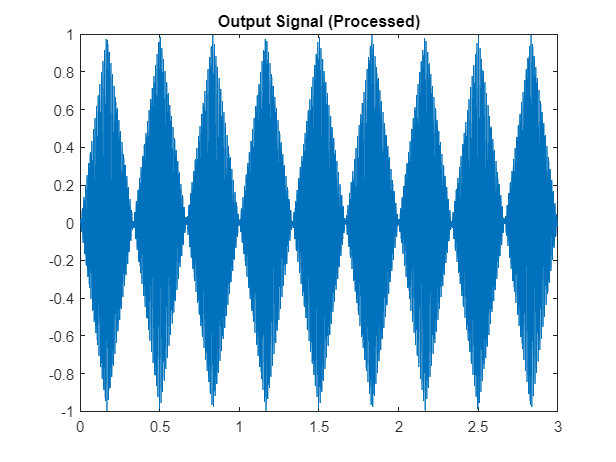

% AUTOPANEXAMPLE
% This script implements the automatic panning (auto–pan)
% effect. The function "pan" is used to process an
% input signal, along with an array of pan values

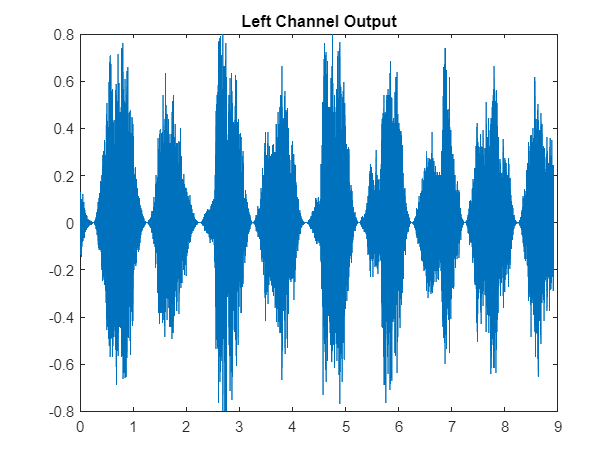

% for each sample number in the signal
%
% See also PAN
% Input Variables
% panType : 1 = linear, 2 = sqRt, 3 = sine–law
% panValue : (–100 to +100)

% User inputted variables
f = 1; % Frequency of panning LFO
panAmp = 100; % Intensity of effect

% Generate sine wave LFO based on f and t
panValue = panAmp*sin(2*pi*f*t);
panType = 3; % Start with panType = 2, but try 1,2,3

% Run pan function
[out] = pan(y,panValue,panType);

sound(out,Fs);

figure
plot(t,out(:,1))
title('Left Channel Output');

figure
plot(t,out(:,2),"Color",[0.8500 0.3250 0.0980])
title('Right Channel Output');

figure

plot(t,out);
legend('Left Channel','Right Channel');

## Echo

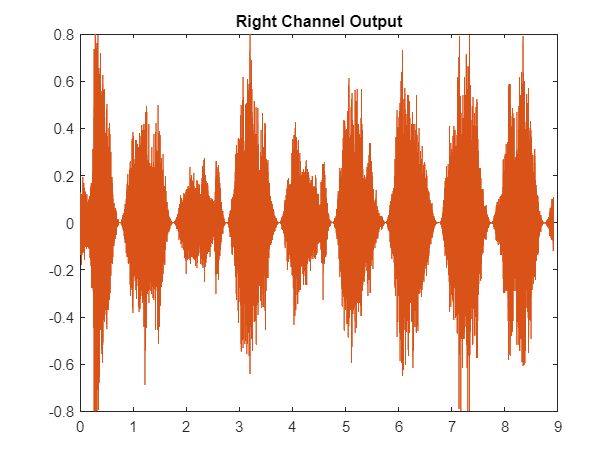

% ECHOFEEDBACK
% This script demonstrates one example to create a

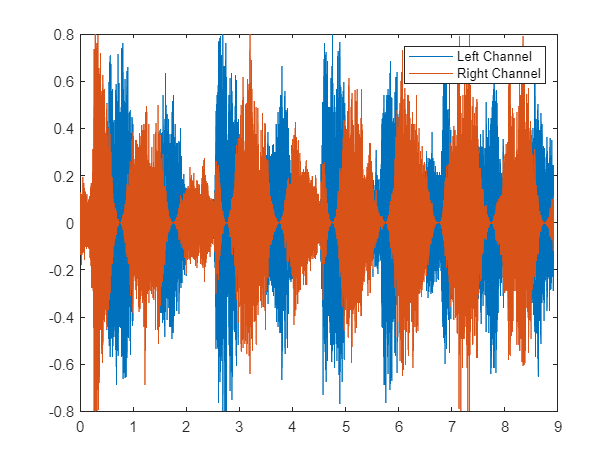

% feedback, tempo–synchronized echo effect
%
% See also ECHOSYNC


% Import our audio file
[x,Fs] = audioread('AcGtr.wav');

% Known tempo of recording
beatsPerMin = 102; % units of beats per minute

% Calculate beats per second
beatsPerSec = beatsPerMin / 60; % 1 minute / 60 seconds

% Calculate # of seconds per beat

Error using audioread>readaudio
The filename specified was not found in the MATLAB path.

Error in audioread (line 137)
    [y, Fs] = readaudio (filename, range, datatype);

secPerBeat = 1/beatsPerSec;

% Note division
% 4 = whole, 2 = half, 1 = quarter, 0.5 = 8th, 0.25 = 16th
noteDiv = 0.5;

% Calculate delay time in seconds
timeSec = noteDiv * secPerBeat;

% Convert to units of samples
d = fix(timeSec * Fs); % round to nearest integer sample

a = -0.75; % amplitude of delay branch

% Index each element of our signal to create the output
N = length(x);
y = zeros(N,1);

for n = 1:N
% When the sample number is less than the time delay
% Avoid indexing a negative sample number
    if n < d+1
    % output = input
    y(n,1) = x(n,1);
    
    % Now add in the delayed signal
    else
    % output = input + delayed version of output
    % reduce relative amplitude of delay to 3/4
    y(n,1) = x(n,1) + (-a)*y(n-d,1);
    end

end

sound(y,Fs); % Listen to the effect

## Reverb

% REVERBCONV
% This script demonstrates the process to create
% a stereo convolution reverb by using a two–channel
% impulse response. This impulse response is based
% on a measurement of a recording studio
% in Nashville, Tennessee.

clear;clc;close all;

% Import sound file and IR measurement
[x,Fs] = audioread('AcGtr.wav'); % Mono signal
[h] = audioread('reverbIR.wav'); % Stereo IR

% Visualize one channel of the impulse response
plot(h(:,1));

% Perform convolution
yLeft = conv(x,h(:,1));
yRight = conv(x,h(:,2));

y = [yLeft,yRight];

sound(y,Fs);

Functions

% PAN
% This function pans a mono audio signal in a stereo field.
% It is implemented such that it can pan the entire signal
% to one location if "panValue" is a scalar. It can also be
% used for auto–pan effects if "panValue" is an array.
%
% Input Variables
% panType : 1 = linear, 2 = sqRt, 3 = sine–law
% panValue : (–100 to +100) transformed to a scale of (0–1)

function [out] = pan(in, panValue, panType)
% Convert pan value to a normalized scale
    panTransform = (panValue/200) + 0.5;
    
    % Conditional statements determining panType
    switch panType
        case 1
            leftAmp = 1 - panTransform;
            rightAmp = panTransform;
        case 2
            leftAmp = sqrt(1 - panTransform);
            rightAmp = sqrt(panTransform);
        case 3
            leftAmp = sin((1 - panTransform) * (pi/2));
            rightAmp = sin(panTransform * (pi/2));
    end
    
    leftChannel = leftAmp.*in;
    rightChannel = rightAmp.*in;
    
    out = [leftChannel,rightChannel];

end